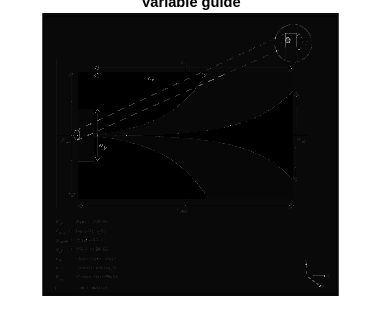

[url_img, map] = imread('https://www.mathworks.com/help/antenna/ref/vivaldiantipodal.png');
figure, imshow(url_img), title('Variable guide');

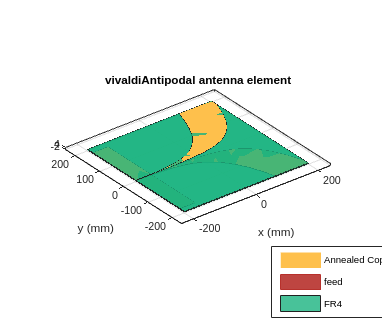

%frequency information
lowest_freq = 300e6;
highest_freq = 900e6;

%generalized offset
offset = 50;

opening_rate = 18;

%variables that match with guide

%%x dimension
l = 0.4;
%%y dimension
w = 0.4;
%%z dimension
PCB_thickness = 1.524e-3;

%%feed thickness
sma_connector_pin_diameter = 1.8e-3;
strip_line_width = sma_connector_pin_diameter;

inner_taper_length = 0.35;
outer_taper_length = inner_taper_length * 0.70;

apature_width = w*0.9;

m = metal(Name = 'Annealed Copper', Conductivity=5.8001e07, Thickness = copper_thickness);
copper_thickness = 4.064e-4;

d = dielectric('Name','FR4','EpsilonR',4.8,'LossTangent',0.026,'Thickness',PCB_thickness);

avi=vivaldiAntipodal( ...
    'BoardLength',l, ...
    'BoardWidth', w, ...
    'Height',PCB_thickness,...
    'OpeningRate',opening_rate, ...
    'GroundPlaneWidth',w*0.9,...
    'ApertureWidth',apature_width,...
    'StripLineWidth', sma_connector_pin_diameter,...
    'InnerTaperLength',inner_taper_length,...
    'OuterTaperLength',outer_taper_length,...
    'Conductor', m,...
    'Substrate', d);
show(avi);

S = sparameters(avi,lowest_freq - offset:1e8:highest_freq + offset);
rfplot(S);

Error using rfplot (line 109)
Undefined function 'rfplot' for input arguments of type 'double'.

impedance(avi,lowest_freq - offset:1e8:highest_freq + offset);

pattern(avi, lowest_freq);
patternAzimuth(avi, lowest_freq);
patternElevation(avi, lowest_freq);

for i = 1:3
    possible_offsets = i*-0.05;
    ava=vivaldiAntipodal( ...
        'BoardLength',l, ...
        'BoardWidth', w, ...
        'Height',PCB_thickness,...
        'OpeningRate',opening_rate, ...
        'GroundPlaneWidth',w*0.9,...
        'ApertureWidth',apature_width,...
        'StripLineWidth', sma_connector_pin_diameter,...
        'InnerTaperLength',inner_taper_length,...
        'OuterTaperLength',outer_taper_length + possible_offsets,...
        'Conductor', m,...
        'Substrate',dielectric('Name','FR4','EpsilonR',4.8,'LossTangent',0.026,'Thickness',PCB_thickness));
    fprintf('Plot %d', i);
    rfplot(sparameters(ava,lowest_freq - offset:1e8:highest_freq + offset));
end